# **pJacobiZeta**

Legandre form of [Jacobi's Zeta function](http://Abramowitz and Stegun. Handbook of Mathematical Functions)

## Definition


$$Z\left(\phi |m\right)=E\left(\phi |m\right)-\frac{E\left(m\right)}{K\left(m\right)}F\left(\phi |m\right)$$



$$Z\left(\phi ,k\right)\equiv Z\left(\phi \left|k^2 \right.\right)$$


where $\phi$is the argument,  *k *is the modulus, *m *is the parameter, $K\left(m\right)$ and $F\left(\phi \left|m\right.\right)$are complete and Legendre elliptic integrals of the first kind*, *$\mathrm{and}\;E\left(m\right)\;\mathrm{and}\;E\left(\phi \left|m\right.\right)$are complete and Legendre   elliptic integrals of the second kind.  $Z\left(\phi \left|m\right.\right)$ is **not ** the periodic part of function $\;E\left(\phi \left|m\right.\right)$.

Domain: If $-\infty <m\le 1$,(or $|k|\le 1$)  then $-\infty \le x\le \infty$. For the specified domain, the  codomain is real numbers.

Basic features:

$Z\left(-\phi \left|m\right.\right)=-Z\left(\phi \left|m\right.\right)$   (odd) 

 $Z\left(\phi +\textrm{n}\pi \left|m\right.\right)=Z\left(\phi \left|m\right.\right),\;\;\;\left|x\right|<\pi /2$  (periodic)

Special values:

$Z\left(0\left|m\right.\right)=0$,   $Z\left(\pi \left|m\right.\right)=0$

$Z\left(\phi \left|0\right.\right)=0$,  $Z\left(\phi \left|1\right.\right)=\mathrm{sin}\;\phi$

Identities:


$$\mathit{\mathbf{Z}}\left(x\left|m\right.\right)=Z\left(\textrm{am}\left(x\left|m\right.\right)\left|m\right.\right)$$



$$Z\left(\phi \left|m\right.\right)\equiv \mathit{\mathbf{Z}}\left({\textrm{am}}^{-1} \left(\phi \left|m\right.\right),m\right)$$


where* sn* and *cd* are the Jacobi elliptic functions, *am *is the Jacobi's amplitude function, and $\mathit{\mathbf{Z}}\left(x\left|m\right.\right)$ is the Jacobi's zeta function.

## Syntax

Y = pJacobiZeta(PHI,K)

y = pjzeta(phi,k)

Y = mpJacobiZeta(PHI,M)

y = mpjzeta(phi,m)

## Description

**Y = pJacobiZeta(PHI,K)** returns the Jacobi zeta function $Z\left(\phi ,k\right)$ for each element of the arrays PHI and K (modulus). PHI and K must be real and the same size or any of them can be scalar. **pJacobiZeta** is the wrapper function which calls the functions **pjzeta** element-wise via the function **ufun2**.

**y = elzeta(phi,k)** returns the Jacobi zeta function $Z\left(\phi ,k\right)$ for argument phi and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed. **pjzeta** is the wrapper function which calls the functions mpjzeta.

**Y = mpJacobiZeta(PHI,M)** returns the Jacobi zeta function $Z\left(\phi \left|m\right.\right)$ for each element of the arrays PHI and M (parameter). PHI and M must be real and the same size or any of them can be scalar. **mpJacobiZeta** is the wrapper function which calls the function **mpjzeta** element-wise via the function **ufun2**.

**y = mpjzeta(phi,m) **returns the Jacobi elliptic function $Z\left(\phi \left|m\right.\right)$ for  argument phi and the parameter m. It is assumed that  arguments are real scalars without check. y is NaN if any of  the arguments is invalid or convergence failed.   **mpjzeta** calculte $Z\left(\phi \left|m\right.\right)$ using Bulirisch's alghorithm  ([1])

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; % |k|<= 1
phi = 0.5;
[pjzeta(phi,k), pJacobiZeta(phi,k), mpjzeta(phi,k^2), mpJacobiZeta(phi,k^2)]

ans =    0.055317014255130   0.055317014255130   0.055317014255130   0.055317014255130


Accuracy. 

fprintf('%.16g\n',mpjzeta(pi/4,-4)) 

-0.6188638522268965


% Maple -0.6188638522268965 09

Special values

m = -20; % m <= 1
phi = -pi/4;  
mpjzeta(0,m)

ans = 0

mpjzeta(pi,m)   % m < 1 !!!

ans = 8.0572e-16

mpjzeta(phi,0)   

ans = 0

disp(mpjzeta(phi,1) - sin(phi))

     0



mpjzeta(phi,inf)

ans = NaN

Identities

m = -2; 
phi = 0.5; % |phi| <= 1
disp(mpJacobiZeta(-phi,m) + mpJacobiZeta(phi,m)) % odd function

     0



mpJacobiZeta(phi,m) - mpEllipticE(phi,m) ...
    + mEllipticE(m)*mpEllipticF(phi,m)/mEllipticK(m)  % definition

ans = 1.1102e-16

m = -2; % |m| < 1
disp(mpjzeta(phi+200*pi,m) - mpjzeta(phi,m))  % periodic function

    -1.332267629550188e-15



disp(pjzeta(phi,k)-jzeta(ijam(phi,k),k))  % check vs second form

    -1.387778780781446e-17



disp(pjzeta(jam(phi,k),k)-jzeta(phi,k))  % check vs second form

     1.387778780781446e-17



**Vector input**

m = [-2, -1,0]'; % |m| < 1
phi = [-10, -1, 10]';
disp(mpJacobiZeta(phi+200*pi,m) - mpJacobiZeta(phi,m))  % periodic function

   1.0e-15 *

  -0.721644966006352
   0.749400541621981
                   0



**Matrix input**

Test identity

format short
m = -2; % |m|< 1
PHI=pi*[-1 0 1 2; 2 3 4 8]

PHI =    -3.1416         0    3.1416    6.2832
    6.2832    9.4248   12.5664   25.1327


disp(mpJacobiZeta(PHI+12*pi*ones(size(PHI)),m) - mpJacobiZeta(PHI,m))  

   1.0e-14 *

    0.4343    0.1271   -0.1801    0.1271
    0.1271    0.4343    0.1271    0.1271



## **Graphs **

**Example 1**

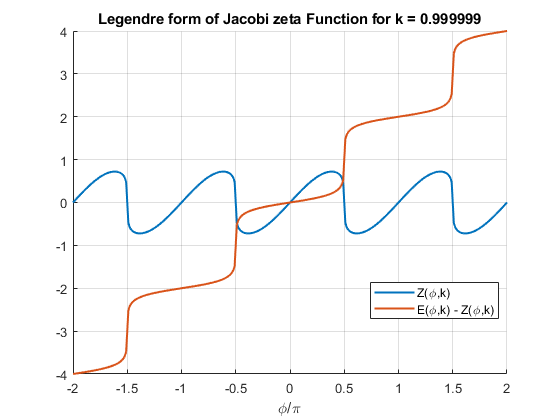

figure
hold on
phi=-2:0.01:2;
k = 0.999999;
plot(phi,pJacobiZeta(pi*phi,k),'LineWidth',1.5)
plot(phi,pEllipticE(pi*phi,k)-pJacobiZeta(pi*phi,k),'LineWidth',1.5)
xlabel('\phi/\pi')
legend('Z(\phi,k)','E(\phi,k) - Z(\phi,k)','Location','best')
ylim([-4 4])
title(sprintf('Legendre form of Jacobi zeta Function for k = %g',k))
grid on

**Example 2**

Example from NIST Mathematical Functions Handbook (Fig 22.16.3)

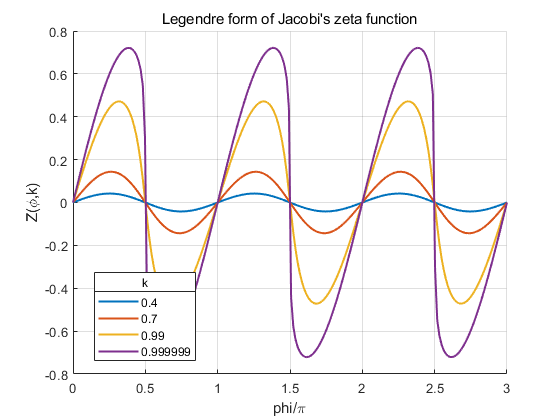

npts = 200;
k = [0.4, 0.7, 0.99, 0.999999];
phi = linspace( 0, 3, npts);
figure
clf
hold on
nn = length(k);
txt{nn}=[];
for n = 1:nn
    txt{n} = num2str(k(n),6);
    plot(phi,pJacobiZeta(pi*phi,k(n)),'LineWidth',1.5)
end
hlg = legend(txt,'Location','best');
title(hlg, 'k','FontWeight','normal')
xlabel('phi/\pi')
ylabel( 'Z(\phi,k)')
ylim([-0.8, 0.8]);
title('Legendre form of Jacobi''s zeta function','FontWeight','normal')
grid on
hold off

**Example 3**

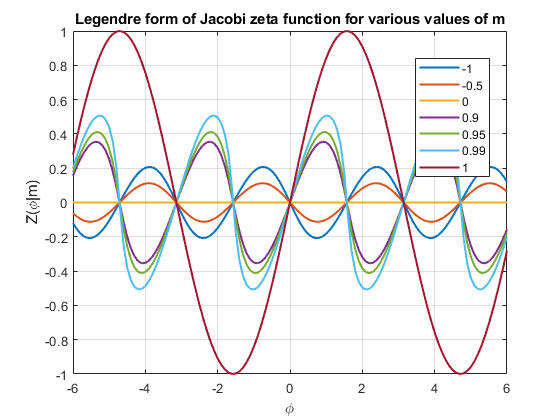

figure
PHI = -6:0.1:6;
M = [-1,-0.5,0,0.9,0.95,0.99,1];
EPS = zeros(length(M),length(PHI));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    EPS(i,:) = mpJacobiZeta(PHI,M(i));
end
plot(PHI,EPS,'LineWidth',1.5)
%axis([min(PHI) max(PHI) -1.2 1.2])
grid on
legend(clg,'Location','Best')
title('Legendre form of Jacobi zeta function for various values of m')
xlabel('\phi')
ylabel('Z(\phi|m)');

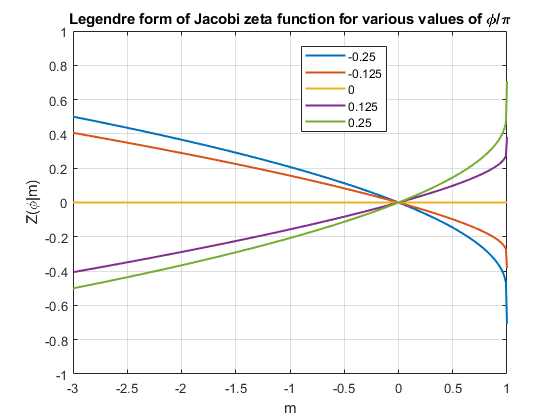

figure
M = -3:0.01:1;
PHI = [-1/4,-1/8,0,1/8,1/4];
SN = zeros(length(PHI),length(M));
clg{length(PHI)}=[];
for i = 1:length(PHI)
     clg{i} = num2str(PHI(i));
    SN(i,:) = mpJacobiZeta(pi*PHI(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -1 1])
grid on
legend(clg{1:length(PHI)},'Location','Best')
title('Legendre form of Jacobi zeta function for various values of \phi/\pi')
xlabel('m')
ylabel('Z(\phi|m)')

**Example 4**

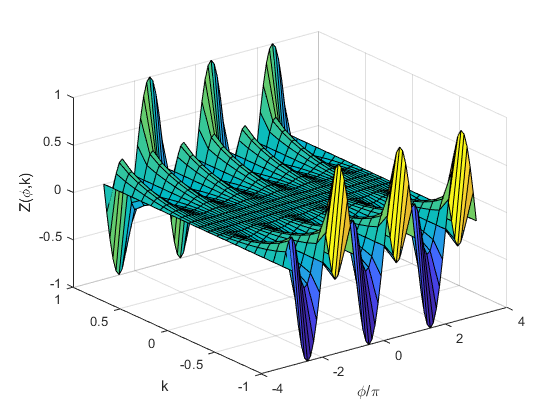

figure
phi=-3:0.1:3;
k=-1:0.1:1;
[PHI,K]=meshgrid(phi,k);
surface(PHI,K,pJacobiZeta(pi*PHI,K))
view(3)
xlabel('\phi/\pi')
ylabel('k')
zlabel('Z(\phi,k)')
grid on

**Example 5**

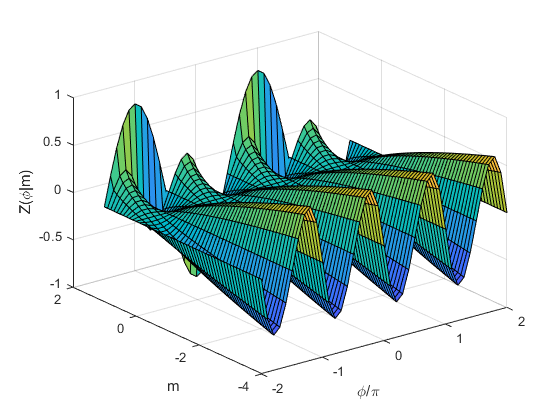

figure
phi=-2:0.1:2;
m=-4:0.1:1;
[PHI,M]=meshgrid(phi,m);
surface(PHI,M,mpJacobiZeta(pi*PHI,M))
view(3)
xlabel('\phi/\pi')
ylabel('m')
zlabel('Z(\phi|m)')
grid on

**Example 6**

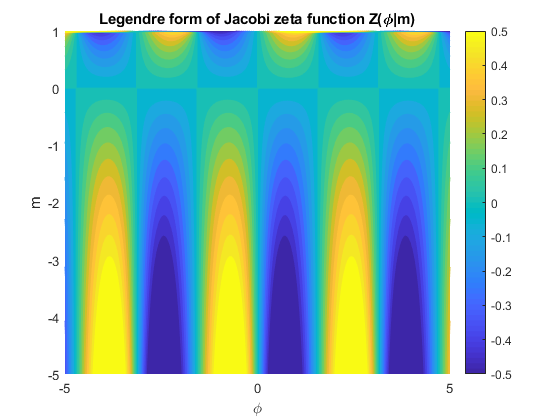

figure
f = @(phi,m)mpJacobiZeta(phi,m);
fcontour(f,[-5,5,-5,1],'Fill','on','LevelList',-0.5:0.05:0.5,'MeshDensity',200)
title('Legendre form of Jacobi zeta function Z(\phi|m)')
colorbar
xlabel('\phi')
ylabel('m')
grid on

**Example 7**

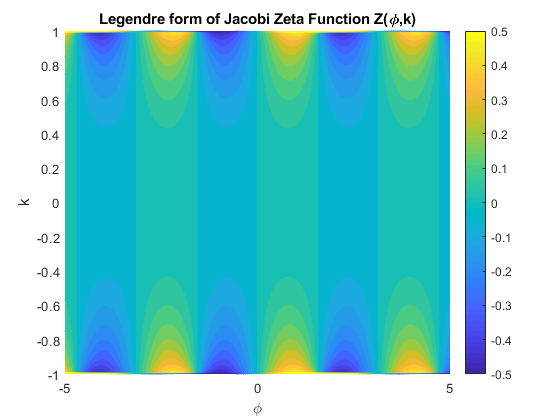

figure
f = @(phi,k)pJacobiZeta(phi,k);
fcontour(f,[-5,5,-1,1],'Fill','on','LevelList',-0.5:0.05:0.5,'MeshDensity',200)
title('Legendre form of Jacobi Zeta Function Z(\phi,k)')
colorbar
xlabel('\phi')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions, part III. Numerische Mathematik 13, 305-315, 1969

## See Also